# CIE Metamerism Index

Q: how to evaluate Mu, Mv shown in papers by Tommy Wei?

A: implement ISO 23605

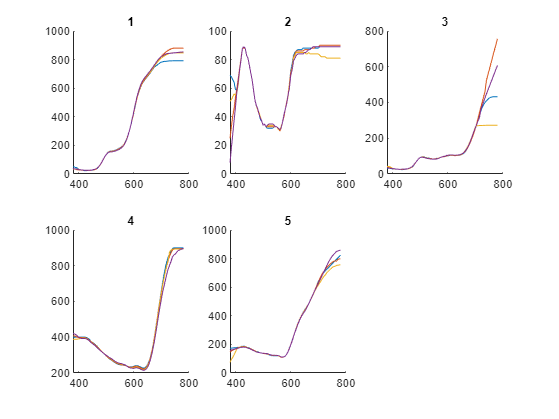

load cie_metamerism_data.mat

spec_ref = specimen;

sp4{1} = spec_d50;
sp4{2} = spec_d55;
sp4{3} = spec_d65;
sp4{4} = spec_d75;

clf
for material_no = 1:5
    subplot(2,3,material_no)
    hold on
    for i = 1:4
        sp = sp4{i};
        plot(sp(:,1),sp(:,1+material_no))
    end
    title(material_no)
end